syms rho s L g F A q x E u(x) r sigma epsilon


F = A*E*g*pi^2/L

$$F = \frac{2778046668940015\,A\,\text{E}\,g}{281474976710656\,L}$$

r=(x/L)^2

$$r = \frac{x^{2}}{L^{2}}$$

q = E*(rho*u-s*r)

$$q(x) = \text{E}\,\left(\rho \,u\left(x\right)-\frac{s\,x^{2}}{L^{2}}\right)$$

epsilon=diff(u,x)

$$epsilon(x) = \frac{\partial }{\partial x}u\left(x\right)$$

sigma=E*epsilon

$$sigma(x) = \text{E}\,\frac{\partial }{\partial x}u\left(x\right)$$


eq = diff(sigma,x)+q==0

$$eq(x) = \text{E}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)+\text{E}\,\left(\rho \,u\left(x\right)-\frac{s\,x^{2}}{L^{2}}\right)=0$$

Du = diff(u,x);
cond=[u(0)==-g, Du(L)==F/(A*E)]

$$cond = \left(\begin{array}{cc} u\left(0\right)=-g & \frac{\partial }{\partial L}u\left(L\right)=\frac{2778046668940015\,g}{281474976710656\,L} \end{array}\right)$$

ODE = dsolve(eq, cond)

$$ODE = \begin{array}{l} \frac{s\,x^{2}}{L^{2}\,\rho }-\frac{2\,s}{L^{2}\,\rho^{2}}+\frac{{\mathrm{e}}^{-\sqrt{-\rho }\,x}\,\left(562949953421312\,\sqrt{-\rho }\,s\,\sigma_{5}+562949953421312\,L\,\rho \,s-\sigma_{1}-281474976710656\,L^{2}\,g\,\sigma_{2}\,\sigma_{5}\right)}{\sigma_{3}}+\frac{{\mathrm{e}}^{\sqrt{-\rho }\,x}\,\left(562949953421312\,\sqrt{-\rho }\,s\,\sigma_{4}-562949953421312\,L\,\rho \,s+\sigma_{1}-281474976710656\,L^{2}\,g\,\sigma_{2}\,\sigma_{4}\right)}{\sigma_{3}}\\ \mathrm{where}\\ \sigma_{1}=2778046668940015\,L\,g\,\rho^{2}\\ \sigma_{2}={\left(-\rho \right)}^{5/2}\\ \sigma_{3}=281474976710656\,L^{2}\,\rho^{2}\,\left(\sqrt{-\rho }\,\sigma_{5}+\sqrt{-\rho }\,\sigma_{4}\right)\\ \sigma_{4}={\mathrm{e}}^{-L\,\sqrt{-\rho }}\\ \sigma_{5}={\mathrm{e}}^{L\,\sqrt{-\rho }} \end{array}$$

clear pi
L_val = 1;
g_val = 0.01;
Solution = subs(ODE,[L g rho s] , [L_val g_val double(pi)^3/L_val^2 (g_val*double(pi)^4)/1^2])

$$Solution = \begin{array}{l} \frac{274182216302020\,x^{2}}{8727491006471547}-\frac{281474976710656\,{\mathrm{e}}^{-\frac{\sqrt{8727491006471547}\,x\,\mathrm{i}}{16777216}}\,\left(\frac{15378346620549804315054983394116493920632986027}{1584563250285286751870879006720}+\frac{60734012678424311367065255549209\,\sqrt{8727491006471547}\,{\mathrm{e}}^{\frac{\sqrt{8727491006471547}\,\mathrm{i}}{16777216}}\,\mathrm{i}}{472236648286964521369600}\right)}{\sigma_{1}}-\frac{281474976710656\,{\mathrm{e}}^{\frac{\sqrt{8727491006471547}\,x\,\mathrm{i}}{16777216}}\,\left(-\frac{15378346620549804315054983394116493920632986027}{1584563250285286751870879006720}+\frac{60734012678424311367065255549209\,\sqrt{8727491006471547}\,{\mathrm{e}}^{-\frac{\sqrt{8727491006471547}\,\mathrm{i}}{16777216}}\,\mathrm{i}}{472236648286964521369600}\right)}{\sigma_{1}}-\frac{154350865896174250719696650240}{76169099268041736439034920573209}\\ \mathrm{where}\\ \sigma_{1}=76169099268041736439034920573209\,\left(\frac{\sqrt{8727491006471547}\,{\mathrm{e}}^{-\frac{\sqrt{8727491006471547}\,\mathrm{i}}{16777216}}\,\mathrm{i}}{16777216}+\frac{\sqrt{8727491006471547}\,{\mathrm{e}}^{\frac{\sqrt{8727491006471547}\,\mathrm{i}}{16777216}}\,\mathrm{i}}{16777216}\right) \end{array}$$

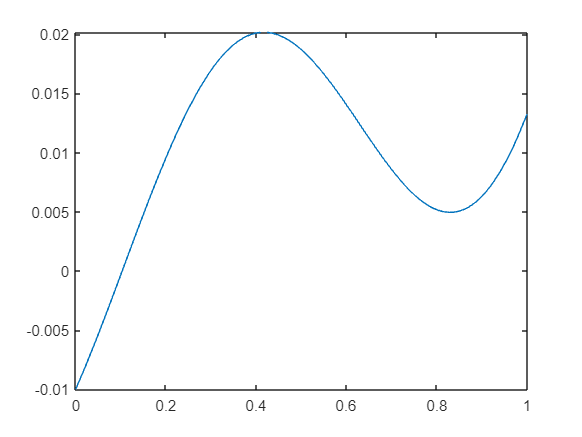


figure
fplot(Solution, [0 L_val])